% read data from simulation
t = out.x_tip.Time;
x = squeeze(out.x_tip.Data);
y = squeeze(out.y_tip.Data);

% m to mm units
t = t(:);
x = x(:) * 1000;
y = y(:) * 1000;

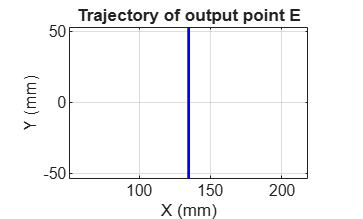

% Plot trajectory x,y
figure;
plot(x, y, 'b-', 'LineWidth', 1.5);
axis equal;
grid on;
xlabel('X (mm)');
ylabel('Y (mm)');
title('Trajectory of output point E');

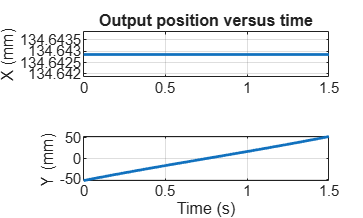


% Plot positions vs time
x_theory = (105^2 - 40^2) / (2 * 35);  % mm
figure;
subplot(2,1,1);
plot(t, x, 'LineWidth', 1.5);
xlim([t(1) t(end)]);
ylim(x_theory + [-0.001 0.001]); % ±0.01 mm

grid on;
ylabel('X (mm)');
title('Output position versus time');

subplot(2,1,2);
plot(t, y, 'LineWidth', 1.5);
xlim([t(1) t(end)])
grid on;
xlabel('Time (s)');
ylabel('Y (mm)');

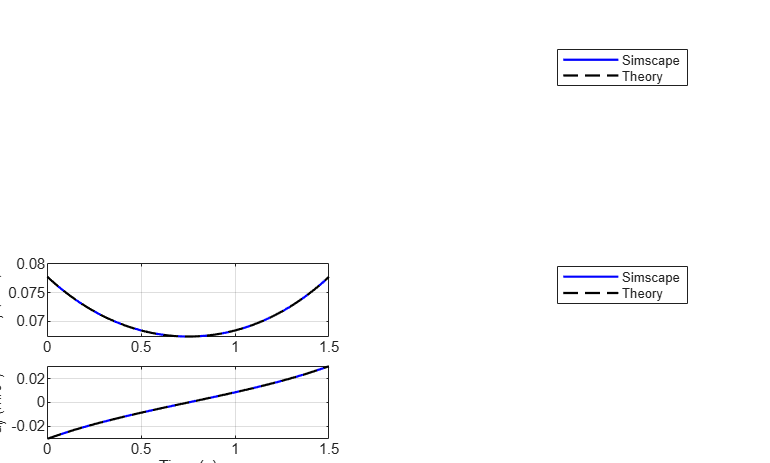

%% Velocity and acceleration of point E
vx = out.vx_P.Data(:);  % m/s
vy = out.vy_P.Data(:);  % m/s
ax = out.ax_P.Data(:);  % m/s^2
ay = out.ay_P.Data(:);  % m/s^2

% Analytical reference from the same geometry and prescribed input
x0 = (L23^2 - L5678^2) / (2 * L4);  % m สำหรับขนาดในโมเดลนี้

switch mode
    case 0  % Linear
        theta    = -amplitude + crankRate * t;
        theta_d  = crankRate * ones(size(t));
        theta_dd = zeros(size(t));

    case 1  % Sin
        theta    = -amplitude * cos(omega * t);
        theta_d  =  amplitude * omega * sin(omega * t);
        theta_dd =  amplitude * omega^2 * cos(omega * t);
end

factor = x0 ./ (2 * cos(theta/2).^2);
vy_theory = factor .* theta_d;
ay_theory = factor .* (theta_dd + tan(theta/2) .* theta_d.^2);

figure;
tiledlayout(2,1);

nexttile;
plot(t, vy, 'b-', t, vy_theory, 'k--', 'LineWidth', 1.2);
grid on;
ylabel('v_y (m/s)');
legend('Simscape', 'Theory', 'Location', 'best');

nexttile;
plot(t, ay, 'b-', t, ay_theory, 'k--', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('a_y (m/s^2)');
legend('Simscape', 'Theory', 'Location', 'best');

fprintf('Max |vy - theory| = %.3e m/s\n', max(abs(vy - vy_theory)));

Max |vy - theory| = 1.581e-13 m/s


[max_ay_error, idx] = max(abs(ay - ay_theory));
fprintf('Max |ay - theory| = %.3e m/s^2 at t = %.2f s\n', ...
    max_ay_error, t(idx));

Max |ay - theory| = 2.373e-11 m/s^2 at t = 0.00 s


fprintf('Max |vx| = %.3e m/s\n', max(abs(vx)));

Max |vx| = 6.396e-14 m/s


fprintf('Max |ax| = %.3e m/s^2\n', max(abs(ax)));

Max |ax| = 9.526e-12 m/s^2


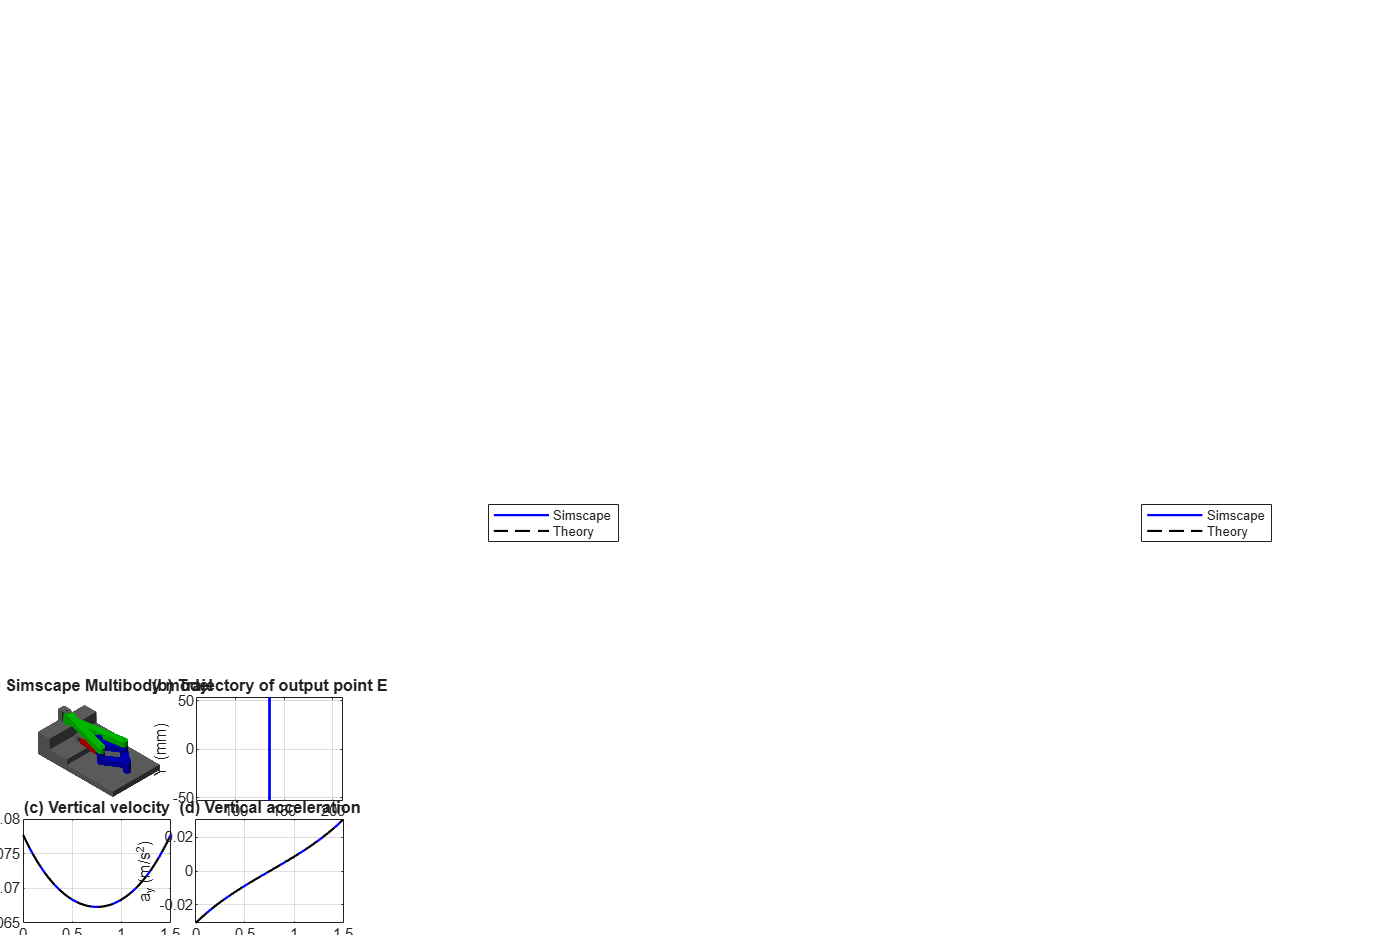

% Combine panels (a)–(d) in one figure
fig = figure('Color', 'w', 'Position', [100 100 1000 680]);
layout = tiledlayout(fig, 2, 2, ...
    'TileSpacing', 'compact', 'Padding', 'compact');

% (a) Model
ax = nexttile(layout);
image(ax, imread('Render.png'));
axis(ax, 'image');
axis(ax, 'off');
title(ax, '(a) Simscape Multibody model');

% (b) Output trajectory
ax = nexttile(layout);
plot(ax, x, y, 'b-', 'LineWidth', 1.5);
axis(ax, 'equal');
grid(ax, 'on');
xlabel(ax, 'X (mm)');
ylabel(ax, 'Y (mm)');
title(ax, '(b) Trajectory of output point E');

% (c) Vertical velocity
ax = nexttile(layout);
plot(ax, t, vy, 'b-', t, vy_theory, 'k--', 'LineWidth', 1.2);
xlim(ax, [t(1) t(end)]);
grid(ax, 'on');
xlabel(ax, 'Time (s)');
ylabel(ax, 'v_y (m/s)');
title(ax, '(c) Vertical velocity');
legend(ax, 'Simscape', 'Theory', 'Location', 'best');

% (d) Vertical acceleration
ax = nexttile(layout);
plot(ax, t, ay, 'b-', t, ay_theory, 'k--', 'LineWidth', 1.2);
xlim(ax, [t(1) t(end)]);
grid(ax, 'on');
xlabel(ax, 'Time (s)');
ylabel(ax, 'a_y (m/s^2)');
title(ax, '(d) Vertical acceleration');
legend(ax, 'Simscape', 'Theory', 'Location', 'best');